unzip("DigitsData.zip");
dataFolder = "DigitsData";
imds = imageDatastore(dataFolder,IncludeSubfolders=true);

Use an augmented image datastore to resize the images to have size 32-by-32 pixels.

imgSize = [32 32];
audsImds = augmentedImageDatastore(imgSize,imds);

numNoiseSteps = 500;
betaMin = 1e-4;
betaMax = 0.02;
varianceSchedule = linspace(betaMin,betaMax,numNoiseSteps);

img = read(audsImds);
img = img{1,1};
img = img{:};
img = rescale(img,-1,1);

tiledlayout("flow");
nexttile
imshow(img,[])
title("t = 0");
for i = 1:5
    nexttile
    noise = randn(size(img),like=img);
    noiseStepsToApply = numNoiseSteps/5 * i;
    noisyImg = applyNoiseToImage(img,noise,noiseStepsToApply,varianceSchedule);

    % Extract the data from the dlarray.
    noisyImg = extractdata(noisyImg);
    imshow(noisyImg,[])
    title("t = " + string(noiseStepsToApply));
end

numInputChannels = 1;
net = createDiffusionNetwork(numInputChannels)

net =   dlnetwork with properties:

         Layers: [205×1 nnet.cnn.layer.Layer]
    Connections: [244×2 table]
     Learnables: [274×3 table]
          State: [0×3 table]
     InputNames: {'imageinput'  'input'}
    OutputNames: {'conv_29'}
    Initialized: 1

  View summary with summary.


T

miniBatchSize = 128;
numEpochs = 50;

learnRate = 0.0005;
gradientDecayFactor = 0.9;
squaredGradientDecayFactor = 0.9999;

doTraining = false;

mbq = minibatchqueue(audsImds, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB", ...
    PartialMiniBatch="discard");

Initialize the parameters for Adam optimization.

averageGrad = [];
averageSqGrad = [];

To track the model performance, use a `trainingProgressMonitor` object. Calculate the total number of iterations for the monitor.

numObservationsTrain = numel(imds.Files);
numIterationsPerEpoch = ceil(numObservationsTrain/miniBatchSize);
numIterations = numEpochs*numIterationsPerEpoch;

Initialize the `TrainingProgressMonitor` object. Because the timer starts when you create the monitor object, make sure that you create the object close to the training loop.

if doTraining
    monitor = trainingProgressMonitor(...
        Metrics="Loss", ...
        Info=["Epoch","Iteration"], ...
        XLabel="Iteration");
end

Train the network.

if doTraining
    iteration = 0;
    epoch = 0;

    while epoch < numEpochs && ~monitor.Stop
        epoch = epoch + 1;
        shuffle(mbq);

        while hasdata(mbq) && ~monitor.Stop
            iteration = iteration + 1;

            img = next(mbq);

            % Generate random noise.
            targetNoise = randn(size(img),Like=img);

            % Generate a random noise step.
            noiseStep = dlarray(randi(numNoiseSteps,[1 miniBatchSize],Like=img),"CB");

            % Apply noise to the image.
            noisyImage = applyNoiseToImage(img,targetNoise,noiseStep,varianceSchedule);

            % Compute loss.
            [loss,gradients] = dlfeval(@modelLoss,net,noisyImage,noiseStep,targetNoise);

            % Update model.
            [net,averageGrad,averageSqGrad] = adamupdate(net,gradients,averageGrad,averageSqGrad,iteration, ...
                learnRate,gradientDecayFactor,squaredGradientDecayFactor);

            % Record metrics.
            recordMetrics(monitor,iteration,Loss=loss);
            updateInfo(monitor,Epoch=epoch,Iteration=iteration);
            monitor.Progress = 100 * iteration/numIterations;
        end

        % Generate and display a batch of generated images.
        numImages = 16;
        displayFrequency = numNoiseSteps + 1;
        generateAndDisplayImages(net,varianceSchedule,imgSize,numImages,numInputChannels,displayFrequency);
    end
else
    % If doTraining is false, download and extract the pretrained network from the MathWorks website.
    pretrainedNetZipFile = matlab.internal.examples.downloadSupportFile('nnet','data/TrainedDiffusionNetwork.zip');
    unzip(pretrainedNetZipFile);
    load("DiffusionNetworkTrained/DiffusionNetworkTrained.mat");
end

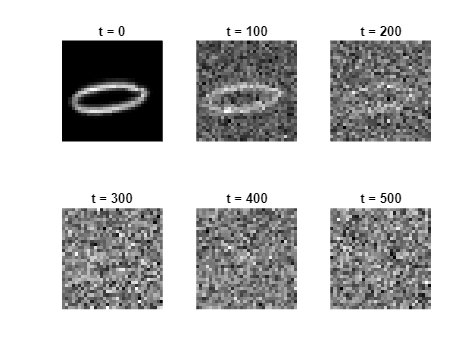

numImages = 9;
displayFrequency = 10;
figure
generatedImages = generateAndDisplayImages(net,varianceSchedule,imgSize,numImages,numInputChannels,displayFrequency);

## Supporting Functions

### Forward Noising Function

The forward noising function `applyNoiseToImage` takes as input an image `img`, a matrix of Gaussian noise `noiseToApply`, an integer `noiseStep` indicating the number of noise steps to apply to the image, and a variance schedule `varianceSchedule`, consisting of a vector of length `numNoiseSteps`.

At each step, the function applies random noise $\varepsilon$ drawn from a standard normal distribution to an image $x_t$ using the following formula:


$$x_{t + 1} = \sqrt{1 - \beta_t} x_t + \sqrt{\beta_t} \varepsilon.$$


To speed up the process of generating noisy images, use the following equation to apply multiple noising steps at once:


$$x_t = \sqrt{\bar{\alpha}_t} x_0 + \sqrt{1 - \bar{\alpha}_t} \varepsilon,$$


where $x_0$ is the original image and $\bar{\alpha}_t = \prod^t_{i = 1} (1 - \beta_i)$.

function noisyImg = applyNoiseToImage(img,noiseToApply,noiseStep,varianceSchedule)
alphaBar = cumprod(1 - varianceSchedule);
alphaBarT = dlarray(alphaBar(noiseStep),"CBSS");

noisyImg = sqrt(alphaBarT).*img + sqrt(1 - alphaBarT).*noiseToApply;
end

### Model Loss Function

The model loss function takes as input the DDPM network `net`, a mini-batch of noisy input images `X`, a mini-batch of noise step values `Y` corresponding to the amount of noise added to each image, and the corresponding target noise values `T`. The function returns the loss and the gradients of the loss with respect to the learnable parameters in `net`.

function [loss, gradients] = modelLoss(net,X,Y,T)
% Forward data through the network.
noisePrediction = forward(net,X,Y);

% Compute mean squared error loss between predicted noise and target.
loss = mse(noisePrediction,T);

gradients = dlgradient(loss,net.Learnables);
end

### Mini-batch Preprocessing Function

The `preprocessMiniBatch` function preprocesses the data using the following steps:

- Extract the image data from the incoming cell array and concatenate into a numeric array.

- Rescale the images to be in the range `[-1,1]`.

function X = preprocessMiniBatch(data)
% Concatenate mini-batch.
X = cat(4,data{:});

% Rescale the images so that the pixel values are in the range [-1 1].
X = rescale(X,-1,1,InputMin=0,InputMax=255);
end

### Image Generation Function

The `generateImages` function takes as input a trained DDPM network `net`, a variance schedule `varianceSchedule`, the image size `imageSize` and the number of desired images `numImages`. The function returns a batch of `numImages` images generated using the following reverse diffusion process:

- Generate a noisy image consisting of Gaussian random noise the same size as the desired image, drawn from a standard normal distribution.

- Use the network to predict the added noise $\varepsilon_\mathrm{pred}$.

- Remove this noise from the image using the formula:

$x_{t - 1} = \frac{1}\sqrt{1 - \beta_t} \left(x_t - \frac{\beta_t}{\sqrt{1 - \bar{\alpha}_t}} \varepsilon_\mathrm{pred} \right) + \sigma_t z$,

            where the posterior variance is $\sigma_t^2 = \frac{1 - \bar{\alpha}_{t-1}}{1 - \bar{\alpha}_t} \beta_t$, and $z$ is a different matrix of Gaussian random noise.

        4. Repeat steps 2-3 for each noise step, counting down from `numNoiseSteps` to `1`.

function images = generateAndDisplayImages(net,varianceSchedule,imageSize,numImages,numChannels,displayFrequency)
% Generate random noise.
images = randn([imageSize numChannels numImages]);

% Compute variance schedule parameters.
alphaBar = cumprod(1 - varianceSchedule);
alphaBarPrev = [1 alphaBar(1:end-1)];
posteriorVariance = varianceSchedule.*(1 - alphaBarPrev)./(1 - alphaBar);

% Reverse the diffusion process.
numNoiseSteps = length(varianceSchedule);

for noiseStep = numNoiseSteps:-1:1
    if noiseStep ~= 1
        z = randn([imageSize,numChannels,numImages]);
    else
        z = zeros([imageSize,numChannels,numImages]);
    end

    % Predict the noise using the network.
    predictedNoise = predict(net,images,noiseStep);

    sqrtOneMinusBeta = sqrt(1 - varianceSchedule(noiseStep));
    addedNoise = sqrt(posteriorVariance(noiseStep))*z;
    predNoise = varianceSchedule(noiseStep)*predictedNoise/sqrt(1 - alphaBar(noiseStep));

    images = 1/sqrtOneMinusBeta*(images - predNoise) + addedNoise;

    % Display intermediate images.
    if mod(noiseStep,displayFrequency) == 0
        tLay = tiledlayout("flow");
        title(tLay,"t = "+ noiseStep)
        for ii = 1:numImages
            nexttile
            imshow(images(:,:,:,ii),[])
        end
        drawnow
    end
end

% Display final images.
tLay = tiledlayout("flow");
title(tLay,"t = 0")
for ii = 1:numImages
    nexttile
    imshow(images(:,:,:,ii),[])
end
end

*Copyright 2023 The MathWorks, Inc.*